clc
clear
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\pixel_videos_directioned_Iqtau\';
% filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\selected_finn_videos_Analysis\';
% filename='deshaked_gray_rescale_crop_fps10_20s_30feet_100000811592 (online-video-cutter.com)_nonAvgIqtau_angle_Iqtau.mat';
% filename='deshaked_gray_rescale_crop_fps10_20s_60feet_100000961607 (online-video-cutter.com)_nonAvgIqtau_angle_Iqtau.mat';
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\nott_video_Analysis\';
filename='compressed_fps10_WinterWheat1_2022-07-25-140826-0000_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
load(input)

angle_num=size(angle_Iqtau,1);
qVec=1:size(angle_Iqtau,2);
q_num=size(angle_Iqtau,2);
tVec=1:size(angle_Iqtau,3);
t_num=size(angle_Iqtau,3);

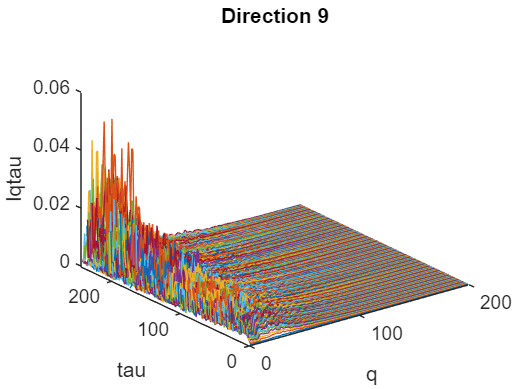

q_max=200;
figure()
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(angle_Iqtau(9,(1:q_max),:)))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 9')

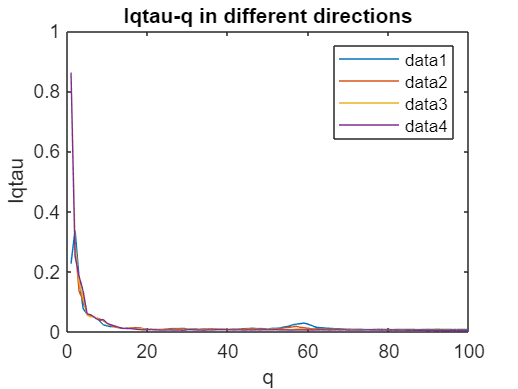

clf
t=10;
q_max=100;
for i=1:angle_num/4
    y=sum(angle_Iqtau(i:i+3,1:q_max,t));
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
clf
t=10;
q_max=100;
for i=1:angle_num
    y=angle_Iqtau(i,1:q_max,t);
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

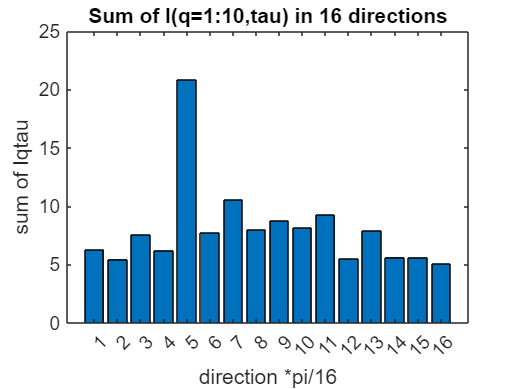

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau(:,1:10,:),2),3)));
xticks(1:angle_num)
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title('Sum of I(q=1:10,tau) in 16 directions')

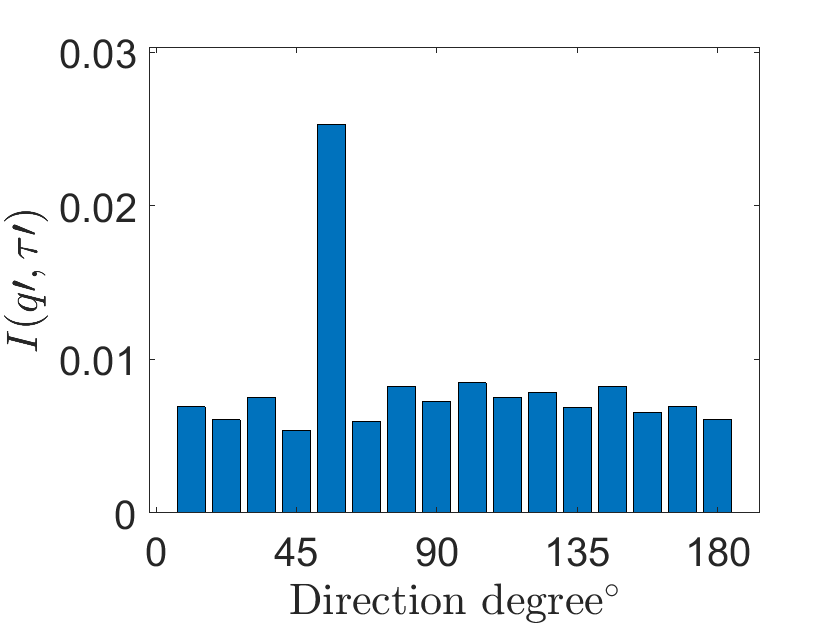

q=3;
tau=3;
fps=10;
scale=1024;
figure()
y=squeeze(sum(sum(angle_Iqtau(:,1:10,tau),2),3));
bar(1:angle_num,y);
xticks(0:4:angle_num);
xticklabels(round(((0:4:angle_num))*180/16,2));
ylim([0 1.2*max(y)])
xlabel('Direction degree$^{\circ}$','Interpreter','latex')
ylabel(['$I(q\prime,\tau\prime)$'],'Interpreter','latex')
% title('Sum of Iqtau in 16 directions')
set(gca,'fontsize', 20);
ax=gca;
ax.YAxis.FontSize = 16;
ax.XAxis.FontSize = 16;

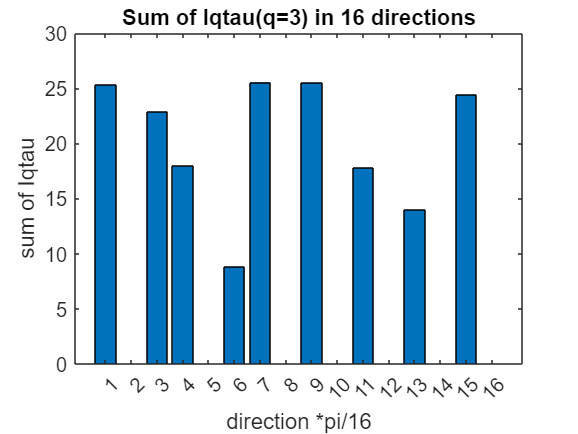

q=3;
figure();
bar(1:angle_num,squeeze(sum(angle_Iqtau(:,q,:),3)));
xticks(1:angle_num)
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title(['Sum of Iqtau(q=' num2str(q) ') in 16 directions'])

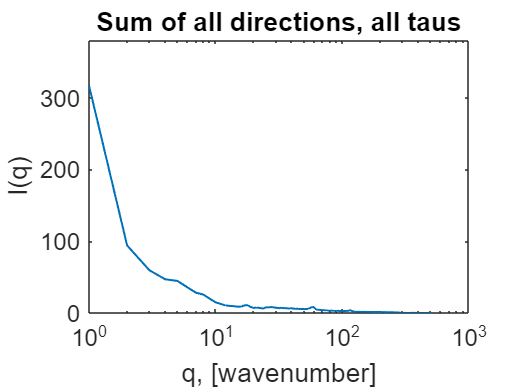

wavelength=1;
scale=1024;
q_max=500;
plotIq_all_dirc_all_tau(filename,path,wavelength,scale,q_max)

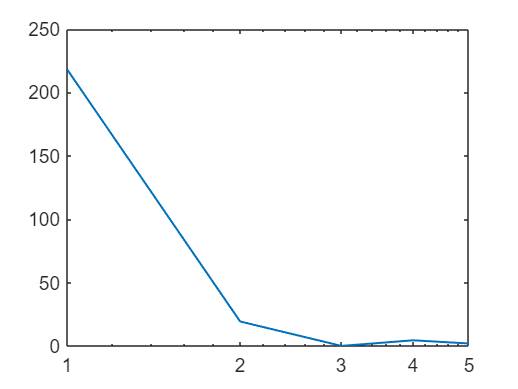

y=sum(sum(angle_Iqtau(5,(1:q_max),:),1),3);
    
semilogx(qVec(1:q_max),squeeze(y),"LineWidth",1)

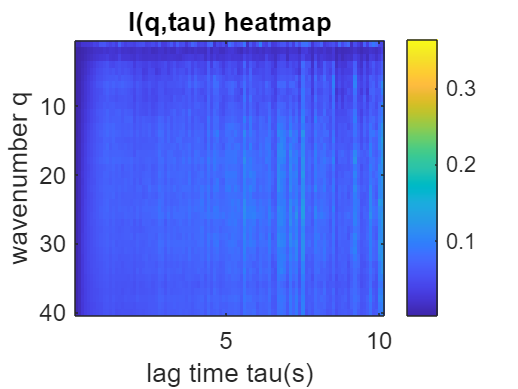

figure()
q_max=40;
imagesc(squeeze(sum(angle_Iqtau(:,1:q_max,:),1)));
xticks([50 100 150 200])
xticklabels({'5','10','15','20'})
xlim([1 100])
xlabel('lag time tau(s)')
ylabel('wavenumber q')
title('I(q,tau) heatmap')
colorbar;
set(gca,'fontsize', 12);

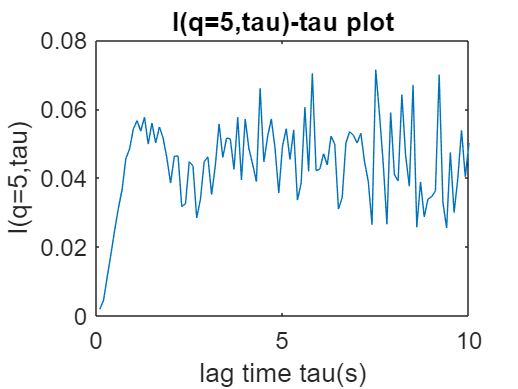

figure()
q=5;
plot(tVec/10,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlim([0 10])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

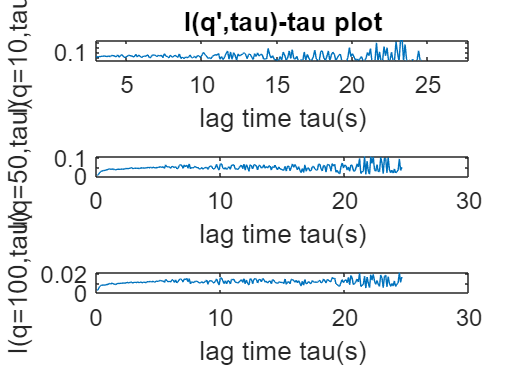

figure()
subplot(3,1,1);
q=10;
plot(tVec/10,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q'',tau)-tau plot'])
set(gca,'fontsize', 12);

subplot(3,1,2);
q=50;
plot(tVec/10,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
% title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

subplot(3,1,3);
q=100;
plot(tVec/10,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
% title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

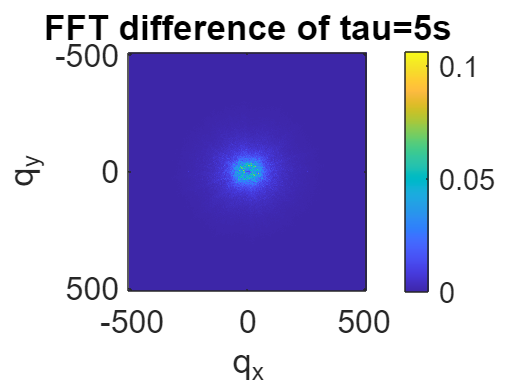

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\nott_video_Analysis\';
filename='compressed_fps10_WinterWheat1_2022-07-25-140826-0000_nonAvgIqtau.mat';
input=[path filename];
theta=0;
wavenumber=0;
scale=1024;
q_range=511;
tau=12;
plotFFTdifference(input,theta,wavenumber,scale,q_range,tau,path)

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\nott_video\';
filename='compressed_fps10_WinterWheat1_2022-07-25-140826-0000.avi';
input=[path filename];
v = VideoReader(input);
frame1 = read(v,1);
frame2 = read(v,13);
diff_frame=frame1-frame2;

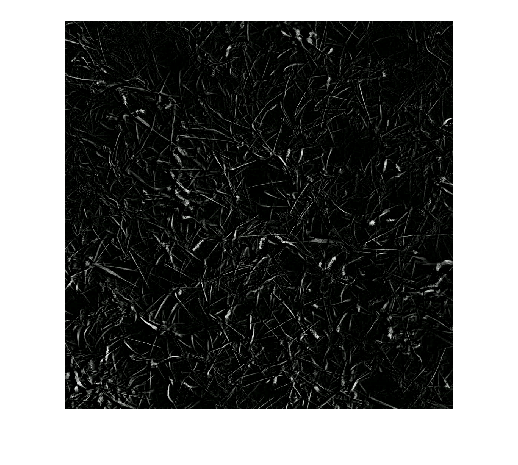

imshow(diff_frame)

% x_label=(0:angle_num-1)*180/angle_num
% strsplit(num2str(round(x_label)))
% set(gca,'xticklabel',{'40 feet','60 feet','120 feet'})

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau,2),3)));

figure()
plot(1:t_num,squeeze(angle_Iqtau(1,1,:)))

imagesc(log(squeeze(sum(angle_Iqtau(5,1:10,:),1))))

% filename='large_fx_0.02_fy_0.02_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0202=load(input);
% 
% filename='large_fx_0.02_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0210=load(input);
% 
% filename='large_fx_0.02_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0200=load(input);

% filename='large_fx_0_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0000=load(input);

q_max=50;
figure()
z=sum(angle_Iqtau(1:16,(1:q_max),:),1);
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(z))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Sum of all directions')

num_of_wave_on_diagonal=1.41;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)


path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\plots\'

clc
filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=6;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.2_fy_0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=12;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.15_fy_0.15_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=8.5;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0.05_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
filename='large_fx_0_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
num_of_wave_on_diagonal=23;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

clc
% filename='large_theta_-2.618(rad)_fx_-0.1_fy_-0.173_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat';
filename='large_theta_-3.1416(rad)_fx_-2.45e-17_fy_-0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray_nonAvgIqtau_angle_Iqtau.mat'
load(filename);
num_of_wave_on_diagonal=8;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
load(filename);
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
load(filename);
num_of_wave_on_diagonal=3;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)

q_max=100;
figure()
y=sum(sum(angle_Iqtau(1:16,(1:q_max),:),1),3)...
    -sum(sum(angle_Iqtau0000.angle_Iqtau(1:16,(1:q_max),:),1),3);
plot(qVec(1:q_max),squeeze(y))
% xlim([0 200])
xlabel('q')
ylabel('Iqtau')
title('Sum of all directions, all taus')

figure()
t=30;
q_max_to_include=3;
q=17; % peak ]
subplot(4,1,1)
plot(1:angle_num,sum(angle_Iqtau0200.angle_Iqtau(:,1:q_max_to_include,t),2))
xlabel('direction')
ylabel('I(q=17,t=16)')
title('f_x=0.02, f_y=0')
subplot(4,1,2)
plot(1:angle_num,sum(angle_Iqtau0202.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.02')
subplot(4,1,3)
plot(1:angle_num,sum(angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.05')
subplot(4,1,4)
plot(1:angle_num,sum(angle_Iqtau0210.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.10')
sgtitle('I in 16 different directions')

d=15;
q=2;
tVec=1:50;
fig=figure();
subplot(3,1,1)
plot(tVec/10,squeeze(angle_Iqtau02.angle_Iqtau(d,q,:)))
title('f_t=0.2Hz')
ylabel('I(q=2,t)')
subplot(3,1,2)
plot(tVec/10,squeeze(angle_Iqtau(d,q,:)))
title('f_t=0.4Hz')
ylabel('I(q=2,t)')
subplot(3,1,3)
plot(tVec/10,squeeze(angle_Iqtau06.angle_Iqtau(d,q,:)))
title('f_t=0.6Hz')
xlabel('time (s)')
ylabel('I(q=2,t)')
sgtitle('I(q=2,t)-t plot for different time frequencies')

saveas(fig,'I(q=2,t)-t plot for different time frequencies.png')


filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.2_gray_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
angle_Iqtau02=load(input);

filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.6_gray_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
angle_Iqtau06=load(input);

surf(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(1,:,:)))

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(1,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 1')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(2,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 2')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(3,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 3')

plot3(repmat((1:598)',1,50),repmat((1:50),598,1),squeeze(angle_Iqtau(4,:,:)))
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 4')

plot(1:50,squeeze(angle_Iqtau(1,30,:)))

scale=846;
plot3(repmat((1-scale/2:scale/2)',1,scale),repmat((1-scale/2:scale/2),scale,1),fftshift(squeeze(nonAvgIqtau(:,:,10))))
xlabel('q_x')
ylabel('q_y')
zlabel('FFT difference')
title('FFT difference at tau=10s')

